
% clc
% clear
load('cone_scan.mat')
% vector_cone = vectors;
% vector_cone = vector_cone(1:50,:)
[num, whatever] = size(vector_cone);

pan_angles = (-120:240/682:120-240/682)*pi/180;    % Convert sensor steps to angles for plotting
[x,y,z] = get_lidar_plane(vector_cone(1,:),pan_angles);
l = 105;


x_servo = zeros(num,682);
y_servo = zeros(num,682);
z_servo = zeros(num,682);


for (i = 0:num-1)
    commanded = i/100;
    tilt_angle = (2.355  * commanded -.8725);
    disp(rad2deg(tilt_angle))
    rotation = rotational(tilt_angle);
    [x,y,z] = get_lidar_plane(vector_cone(i+1,:),pan_angles);
    mat = [x;y;z];
%     test = rotation*[3;1;0];
%     disp(tilt_angle);
%     disp(test);
    for (j = 1:682)
        tmp = rotation*mat(:,j);

        x_servo(i+1,j) = tmp(1);
        y_servo(i+1,j) = tmp(2) + l*cos(tilt_angle);
        z_servo(i+1,j) = tmp(3) + l*sin(tilt_angle);

%         disp(rot_mat);
    end
end

  -49.9906

  -48.6413

  -47.2919

  -45.9426

  -44.5933

  -43.2440

  -41.8947

  -40.5454

  -39.1960

  -37.8467

  -36.4974

  -35.1481

  -33.7988

  -32.4495

  -31.1001

  -29.7508

  -28.4015

  -27.0522

  -25.7029

  -24.3536

  -23.0043

  -21.6549

  -20.3056

  -18.9563

  -17.6070

  -16.2577

  -14.9084

  -13.5590

  -12.2097

  -10.8604

   -9.5111

   -8.1618

   -6.8125

   -5.4632

   -4.1138

   -2.7645

   -1.4152

   -0.0659

    1.2834

    2.6327

    3.9821

    5.3314

    6.6807

    8.0300

    9.3793

   10.7286

   12.0780

   13.4273

   14.7766

   16.1259



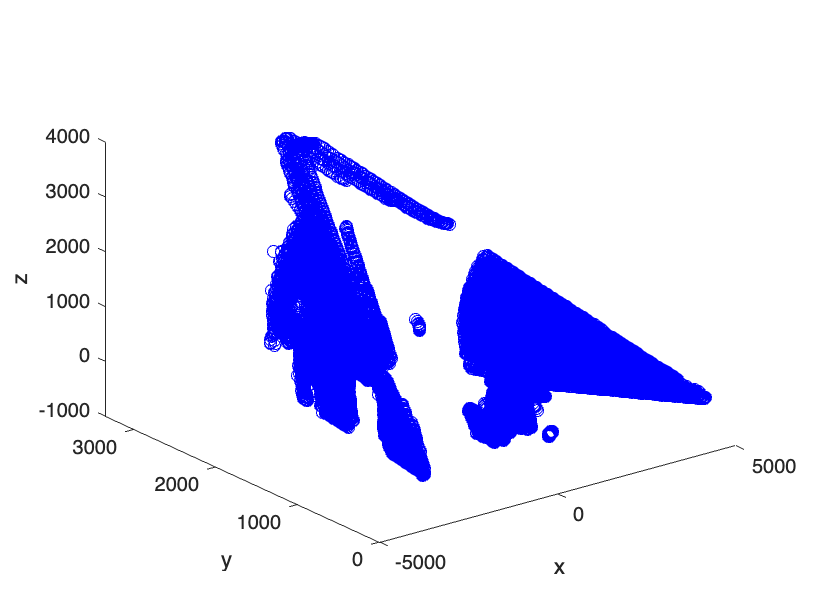

plot3(x_servo,y_servo, -z_servo,'o','color','b')
xlabel('x')
ylabel('y')
zlabel('z')
ylim([0,inf])

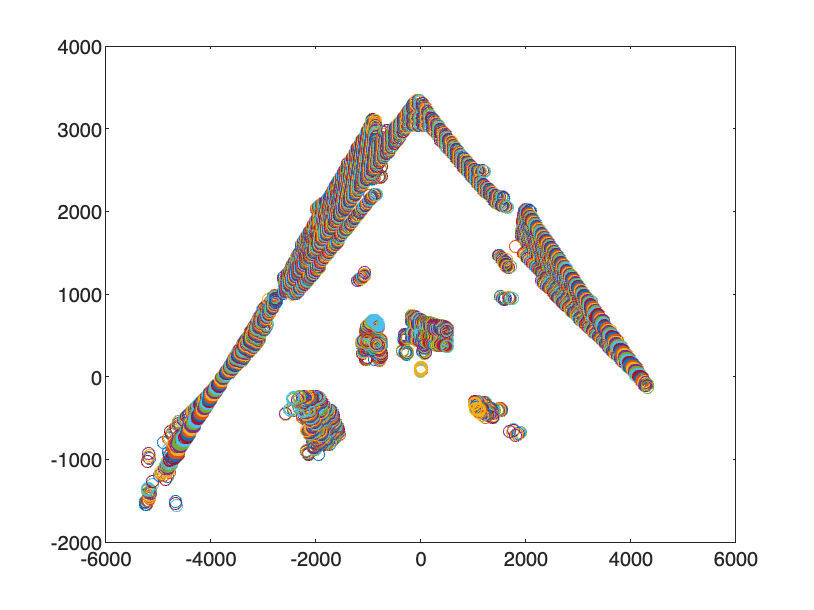

plot(x_servo,y_servo,'o')

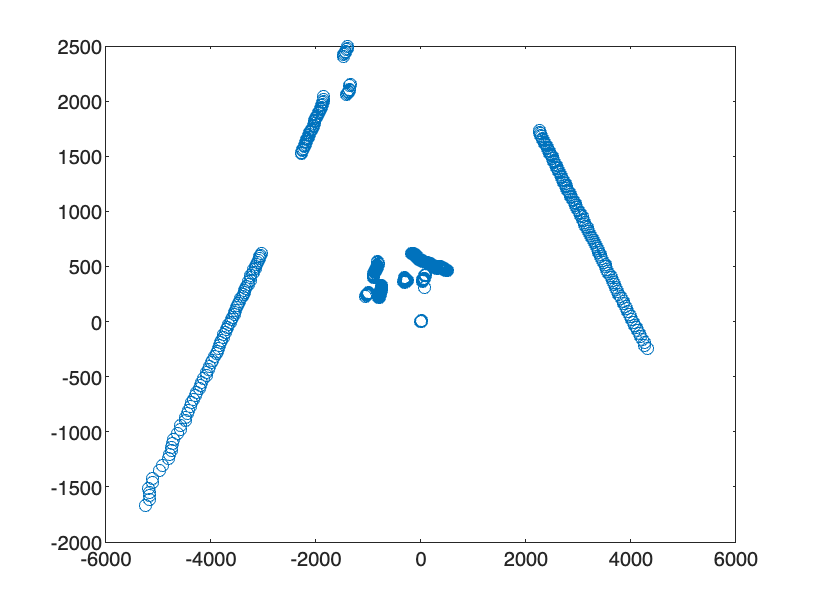

plot(x,y,'o')

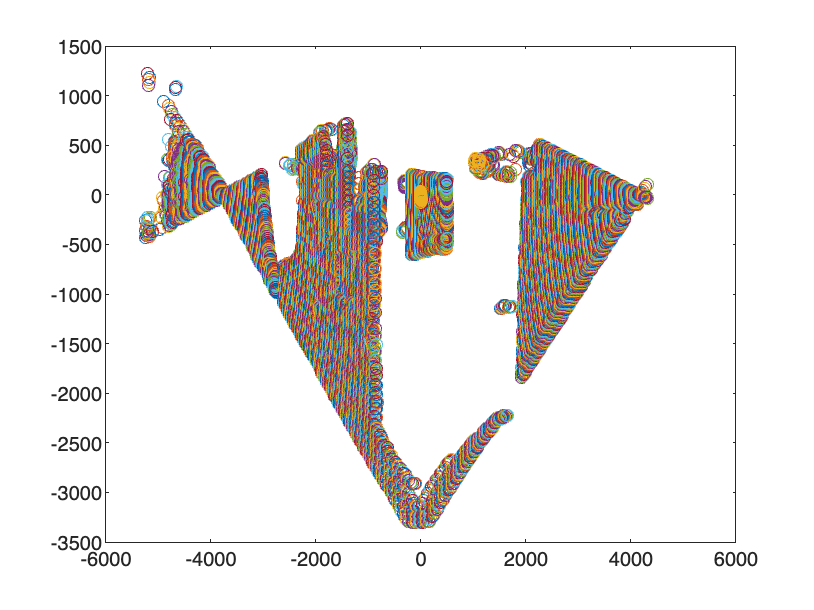

plot(x_servo,z_servo,'o')

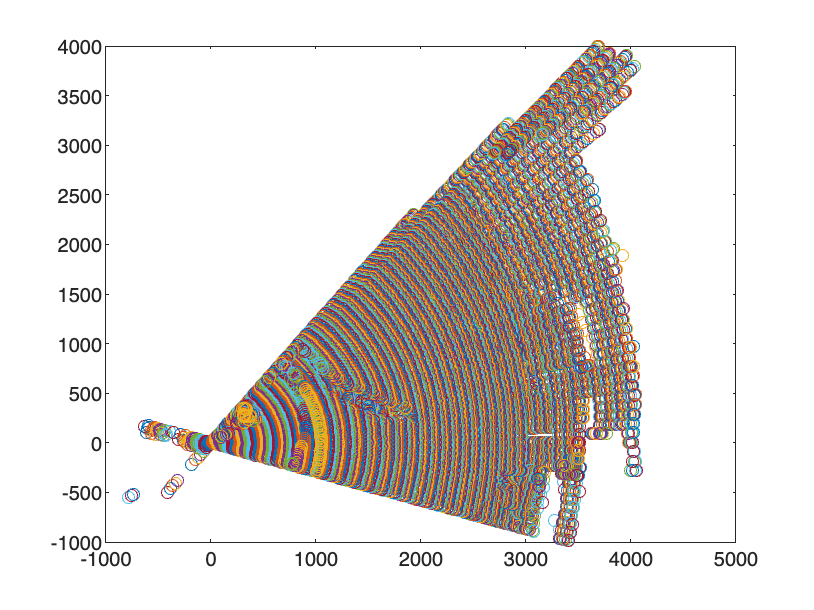

plot(y_servo,-z_servo,'o')

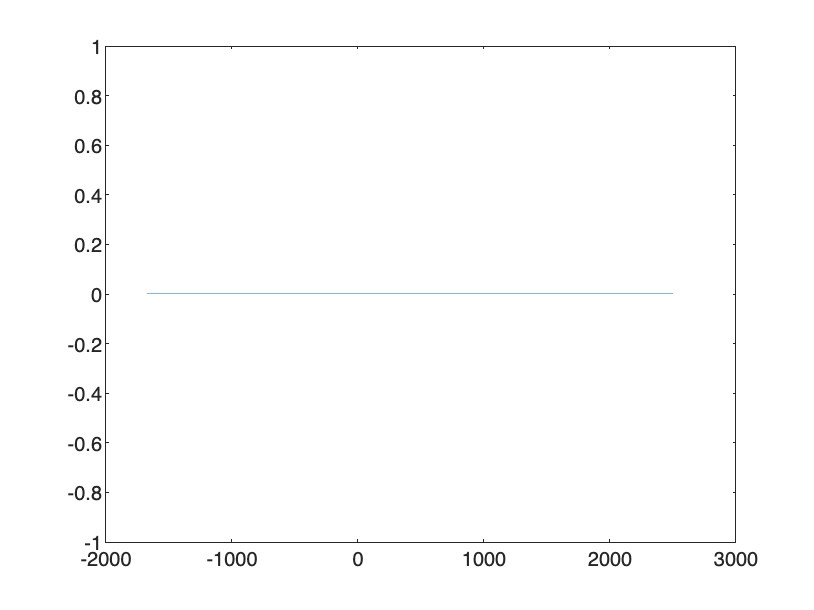

plot(y,z)

mid = 682/2-100;
window_size = 80;

x_filter = zeros(num,window_size*2+1);
y_filter = zeros(num,window_size*2+1);
z_filter = zeros(num,window_size*2+1);

for (i=1:num)
    x_filter(i,:) = x_servo(i,mid-window_size:mid+window_size);
    y_filter(i,:) = y_servo(i,mid-window_size:mid+window_size);
    z_filter(i,:) = z_servo(i,mid-window_size:mid+window_size);
end

plot3(x_filter,y_filter,z_filter,'o','Color','b')

Unrecognized function or variable 'x_filter'.

xlabel('x')
ylabel('y')
zlabel('z')


function [x,y,z] = get_lidar_plane(d,pan_angles)
    y = d.*cos(pan_angles);
    x = d.*sin(pan_angles);
%     z = 1150*ones(1,682);
    z = zeros(1,682);
end

function [rotation] = rotational(theta)
%     rotation = [1 0 0 ; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
    rotation = rotx(rad2deg(theta));
end